# Immune scDRSA

**Author**: Scott Campit

## Summary

This script computes differentially sensitive reactions resulting from reaction knockouts in the metabolic reconstruction.

clear all;
load D:\Analysis\Immune\neutrophil_scFBA.mat
%load ~/Analysis/Immune/neutrophil_scFBA.mat

Get a new string ID to partition by day

% Separate based on day
tmp_id = split(neutrophil_id, " ");
tmp_id = string(floor(double(tmp_id(:, 3))));

% Indicies based on day
idx0 = tmp_id == "0";
idx7 = tmp_id == "7";
idx14 = tmp_id == "14";
idx21 = tmp_id == "21";

## Relative flux analysis

This code block analyzes the relative change between time points from the knockout results. 

Now let's get flux distributions corresponding to different days.

flux0 = tmpflx(idx0, :);
flux7 = tmpflx(idx7, :);
flux14 = tmpflx(idx14, :);
flux21 = tmpflx(idx21, :);

Now get fold change across different time points. I added a value of 1 to not run into infinite values.

fc0007 = (abs(flux7)+1) ./ mean(abs(flux0)+1);
fc0714 = (abs(flux14)+1) ./ mean(abs(flux7)+1);
fc1421 = (abs(flux21)+1) ./ mean(abs(flux14)+1);

Concatenate vertically

df = [fc0007; fc0714; fc1421];

Get reaction IDs

ids = [model.rxns, model.rxnNames, model.subSystems];

comps = string(model.comps);
for i = 1:length(model.metComps)
    metcomp(i, 1) = comps(model.metComps(i));
end
model.mets = strcat(string(model.metNames), '_', metcomp);

Remove reactions that have no fold change in any reaction. 

keep_idx = all(df-1, 1);
df = df(:, keep_idx);
ids = ids(keep_idx, :);

Let's also apply the log2 operator on the data.

df = log2(df);

Let's plot a histogram of the data distribution.

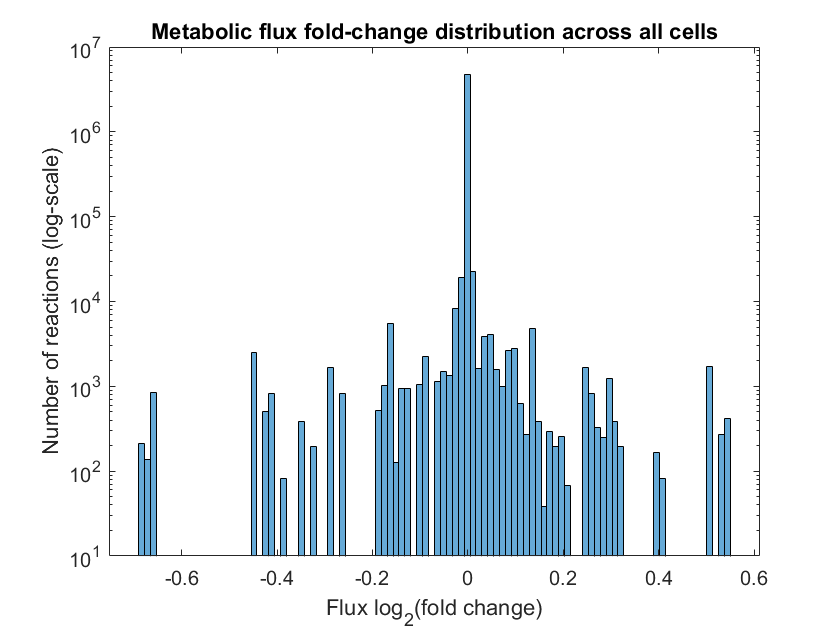

histogram(df, 100);
xlabel("Flux log_{2}(fold change)");
ylabel("Number of reactions (log-scale)");
title("Metabolic flux fold-change distribution across all cells")
set(gca, 'YScale', 'log');

Create an average matrix for each time point and visualize that

df07 = df(1:sum(idx7), :);
df14 = df((sum(idx7)+1):(sum(idx14)+sum(idx7)), :);
df21 = df((sum(idx14)+sum(idx7)+1):sum(idx14)+sum(idx7)+sum(idx21), :);

### Compute average and standard deviation of metabolic fluxes for single cells

First, let's compute the average metabolic flux fold changes.

avg_df07 = mean(df07, 1);
avg_df14 = mean(df14, 1);
avg_df21 = mean(df21, 1);

We'll make a single matrix and take the sume of averages across all time points.

% Construct a single matrix of the average metabolic flux fold changes
avg_df = [avg_df07; avg_df14; avg_df21];

% Get the sum of averages across all time points
avg_overall = sum(avg_df, 1);

Let's plot a histogram of the data distribution.

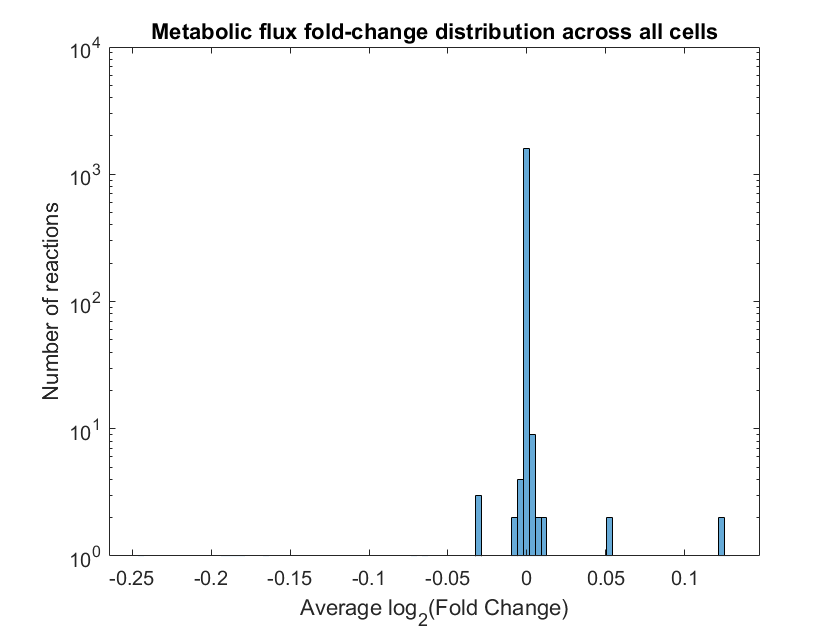

histogram(avg_overall, 100);
xlabel("Average log_{2}(Fold Change)");
ylabel("Number of reactions");
title("Metabolic flux fold-change distribution across all cells")
set(gca, 'YScale', 'log');

We'll also compute the variances

% Compute variance of metabolic flux fold changes
var_df07 = var(df07, 1);
var_df14 = var(df14, 1);
var_df21 = var(df21, 1);

We'll make a single matrix and take the sume of variances across all time points.

% Construct a single matrix of the variances
var_df = [var_df07; var_df14; var_df21];

% Get the sum of variance across all time points
var_overall = sum(var_df, 1);

Sort the reactions by overall averages.

% Sort by descending
[~, idx] = sort(avg_overall, 'descend');
avg_ids = string(ids);

% Apply descend to matrix
final_df = avg_ids;

We need to make a string out of the data.

tmp = [avg_df07', var_df07', ...
       avg_df14', var_df14', ...
       avg_df21', var_df21', ...
       avg_overall', var_overall'];
tmp = string(tmp);

Now concatenate all of the data

final_df = [final_df, tmp];
final_df = final_df(idx, :);

Filter by the variance. I chose an arbitrary threshold of 1E-5.

idx2 = double(final_df(:, 11)) > 1E-5;
final_df = final_df(idx2, :);

Map back the reaction formula to the reactions.

rxn = printRxnFormula(model, 'rxnAbbrList', cellstr(final_df(:, 1)));

HMR_4418	IMP_c + PPi_c 	<=>	hypoxanthine_c + PRPP_c 
HMR_4574	inosine_c + Pi_c 	<=>	hypoxanthine_c + ribose-1-phosphate_c 
INSK	ATP_c + inosine_c 	->	ADP_c + H+_c + IMP_c 
HMR_4586	H+_m + NADPH_m + oxalosuccinate_m 	<=>	isocitrate_m + NADP+_m 
HMR_4588	H+_m + NADH_m + oxalosuccinate_m 	<=>	isocitrate_m + NAD+_m 
HMR_6027	AKG_c + butyrate_s 	<=>	AKG_s + butyrate_c 
BUTt2r	butyrate_s + H+_s 	<=>	butyrate_c + H+_c 
HMR_6373	H+_s + proline_s 	->	H+_c + proline_c 
HMR_5076	glycine_s 	->	glycine_c 
HMR_9078	HCO3-_s 	->	
HMR_5448	HCO3-_c + 2 Na+_c 	->	HCO3-_s + 2 Na+_s 
HMR_3956	CO2_m + H2O_m 	->	H+_m + HCO3-_m 
r0941	HCO3-_c 	<=>	HCO3-_m 
HMR_5084	cysteine_s 	->	cysteine_c 
HMR_4312	D-glucitol_c 	<=>	D-glucitol_s 
HMR_9685	D-glucitol_s 	->	
RE1342C	D-glucitol_c + NAD+_c 	<=>	glucose_c + H+_c + NADH_c 
HMR_5077	alanine_s 	->	alanine_c 
THFt2	H2O_c + THF_s 	<=>	H2O_s + THF_c 
FOLt2	folate_s + H2O_c 	<=>	folate_c + H2O_s 
HMR_7684	folate_c + hydroxide_s 	<=>	folate_s + hydroxide_c 
HMR_7685	hyd

Create the final matrix.

final_df = [string(rxn), final_df];
final_df = ["Formula", "ID", "Name", "Subsystem", ...
            "Mean Day 7", "Var Day 7", ...
            "Mean Day 14", "Var Day 14", ...
            "Mean Day 21", "Var Day 21", ...
            "Mean Overall", "Var Overall"; ...
            final_df];

### Compute median and median absolute deviation of metabolic fluxes for single cells

Median of metabolic fluxes

% Compute median flux fold changes
med_df07 = median(df07, 1);
med_df14 = median(df14, 1);
med_df21 = median(df21, 1);

We'll make a single matrix and take the sum of medians across all time points.

% Construt a single matrix
med_df = [med_df07; med_df14; med_df21];

% Get the overall median across all time points
med_overall = sum(med_df, 1);

Median absolute deviation of metabolic fluxes

% Compute MAD
mad_df07 = mad(df07, 1);
mad_df14 = mad(df14, 1);
mad_df21 = mad(df21, 1);

% Construct a single matrix
mad_df = [mad_df07; mad_df14; mad_df21];

% Get the overall MAD across all time points
mad_overall = sum(mad_df, 1);

% Sort by descend
[~, idx] = sort(med_overall, 'descend');
med_ids = string(ids);

% Apply descend to matrix
final_med_df = med_ids;

We need to make a string out of the data.

tmp = [med_df07', mad_df07', ...
       med_df14', mad_df14', ...
       med_df21', mad_df21', ...
       med_overall', mad_overall'];
tmp = string(tmp);

Now concatenate all of the data

final_med_df = [final_med_df, tmp];
final_med_df = final_med_df(idx, :);

Filter by the variance. I chose an arbitrary threshold of 1E-5.

idx2 = double(final_med_df(:, 11)) > 1E-5;
final_med_df = final_med_df(idx2, :);

Map back the reaction formula to the reactions.

rxn = printRxnFormula(model, 'rxnAbbrList', cellstr(final_med_df(:, 1)));

HMR_4888	H2O_c 	<=>	H2O_m 
HMR_6024	AKG_c + propanoate_s 	<=>	AKG_s + propanoate_c 
PPASMCT1	Na+_s + propanoate_s 	<=>	Na+_c + propanoate_c 
HMR_3802	AKG_m + 2 H+_m + NADH_m + NH3_m 	<=>	glutamate_m + H2O_m + NAD+_m 
HMR_3804	AKG_m + 2 H+_m + NADPH_m + NH3_m 	<=>	glutamate_m + H2O_m + NADP+_m 
HMR_1694	3alpha,7alpha-dihydroxy-5beta-cholestanate_c 	<=>	3alpha,7alpha-dihydroxy-5beta-cholestanate_m 
HMR_1774	5beta-cholestane-3alpha,7alpha,26-triol_c 	->	5beta-cholestane-3alpha,7alpha,26-triol_m 
HMR_1684	3alpha,7alpha-dihydroxy-5beta-cholestan-26-al_c + H+_c + NADH_c 	<=>	5beta-cholestane-3alpha,7alpha,26-triol_c + NAD+_c 
RE1804M	5beta-cholestane-3alpha,7alpha,26-triol_m + NAD+_m 	<=>	3alpha,7alpha-dihydroxy-5beta-cholestan-26-al_m + H+_m + NADH_m 
RE1807M	3alpha,7alpha-dihydroxy-5beta-cholestan-26-al_m + H2O_m + NADP+_m 	<=>	3alpha,7alpha-dihydroxy-5beta-cholestanate_m + 2 H+_m + NADPH_m 
HMR_1692	3alpha,7alpha-dihydroxy-5beta-cholestan-26-al_c + H2O_c + NAD+_c 	<=>	3alpha,7alpha-dihydr

Create the final matrix.

final_med_df = [string(rxn), final_med_df];
final_med_df = ["Formula", "ID", "Name", "Subsystem", ...
            "Mean Day 7", "Var Day 7", ...
            "Mean Day 14", "Var Day 14", ...
            "Mean Day 21", "Var Day 21", ...
            "Mean Overall", "Var Overall"; ...
            final_med_df];

## Get the genes from the dataframes of interest

### Mean + Variance 

tmp = model;
tmp.genes = tmp.geneSymbol;
genelst = findGenesFromRxns(tmp, cellstr(final_df(:, 2)))

The reaction "ID" is not in your model!


genelst = 54×1 cell array
    { 1×1 cell}
    { 1×1 cell}
    { 0×1 cell}
    { 2×1 cell}
    { 2×1 cell}
    { 7×1 cell}
    { 1×1 cell}
    { 4×1 cell}
    {12×1 cell}
    { 0×1 cell}
    { 2×1 cell}
    { 2×1 cell}
    { 0×1 cell}
    {11×1 cell}
    { 7×1 cell}
    { 0×1 cell}


### Median + MAD 

tmp = model;
tmp.genes = tmp.geneSymbol;
genelst = findGenesFromRxns(tmp, cellstr(final_med_df(:, 2)))

The reaction "ID" is not in your model!


genelst = 77×1 cell array
    { 1×1 cell}
    { 7×1 cell}
    { 1×1 cell}
    { 2×1 cell}
    { 2×1 cell}
    { 4×1 cell}
    { 0×1 cell}
    { 8×1 cell}
    { 1×1 cell}
    { 1×1 cell}
    { 5×1 cell}
    { 0×1 cell}
    { 1×1 cell}
    {44×1 cell}
    {19×1 cell}
    { 3×1 cell}


% Data distribution
figure;
histogram(mad_df(4, :));

Index in position 1 exceeds array bounds (must not exceed 3).

set(gca, 'YScale', 'log');
title('Distribution of Medium Absolute Deviation');
xlabel("MAD");
ylabel("Number of reactions (log-scale)")

avg_df = avg_df';
heatmap(avg_df, ...
    "YDisplayLabels", "");